# Optimización unidimensional usando el método de Newton en MATLAB

**Profesor:** PhD. Marlon E. Moscoso Martínez

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo y sus derivadas
f = @(x) x.^3 - 3*x + 4;
df = @(x) 3*x.^2 - 3;
d2f = @(x) 6*x;

% Paso 1: Definir los parámetros del método de Newton
x_k = -2;  % Punto inicial
delta = 1e-6;  % Tolerancia para la convergencia
max_iter = 100;  % Número máximo de iteraciones

% Inicialización de variables
iter = 0;
error_1 = delta + 1;  % Error basado en |x_{k+1} - x_k|
error_2 = delta + 1;  % Error basado en |f'(x_{k+1})|
x_hist = x_k;  % Historial de puntos x
errors_1 = []; % Almacenar errores tipo 1
errors_2 = []; % Almacenar errores tipo 2
f_hist = f(x_k); % Historial de valores de f(x)

% Bucle del método de Newton
while (error_1 > delta || error_2 > delta) && iter < max_iter
    iter = iter + 1;
    
    % Paso 2: Evaluar las derivadas
    f_prime = df(x_k);
    f_double_prime = d2f(x_k);
    
    % Paso 3: Actualizar el valor de x_k
    x_k_plus_1 = x_k - f_prime / f_double_prime;
    
    % Guardar valores para análisis
    x_hist = [x_hist, x_k_plus_1];
    f_hist = [f_hist, f(x_k_plus_1)];
    error_1 = abs(x_k_plus_1 - x_k);
    error_2 = abs(df(x_k_plus_1));
    errors_1 = [errors_1, error_1];
    errors_2 = [errors_2, error_2];
    
    % Actualizar x_k
    x_k = x_k_plus_1;
end

% Valor óptimo de x
x_opt = x_k;
f_opt = f(x_opt);

% Crear una tabla con los resultados de las iteraciones
iterations = (0:iter)';
table_results = table(iterations, x_hist', f_hist', [NaN; errors_1'], [NaN; errors_2'], ...
    'VariableNames', {'Iteración', 'x', 'f(x)', 'Error |x_k+1 - x_k|', 'Error |f''(x_k)|'});

% Mostrar la tabla
disp('Tabla de resultados:');

Tabla de resultados:


disp(table_results);

    Iteración       x        f(x)     Error |x_k+1 - x_k|    Error |f'(x_k)|
    _________    _______    ______    ___________________    _______________

        0             -2         2               NaN                  NaN   
        1          -1.25    5.7969              0.75               1.6875   
        2         -1.025    5.9981             0.225              0.15187   
        3        -1.0003         6          0.024695            0.0018295   
        4             -1         6        0.00030483           2.7877e-07   
        5             -1         6        4.6461e-08           6.6613e-15   



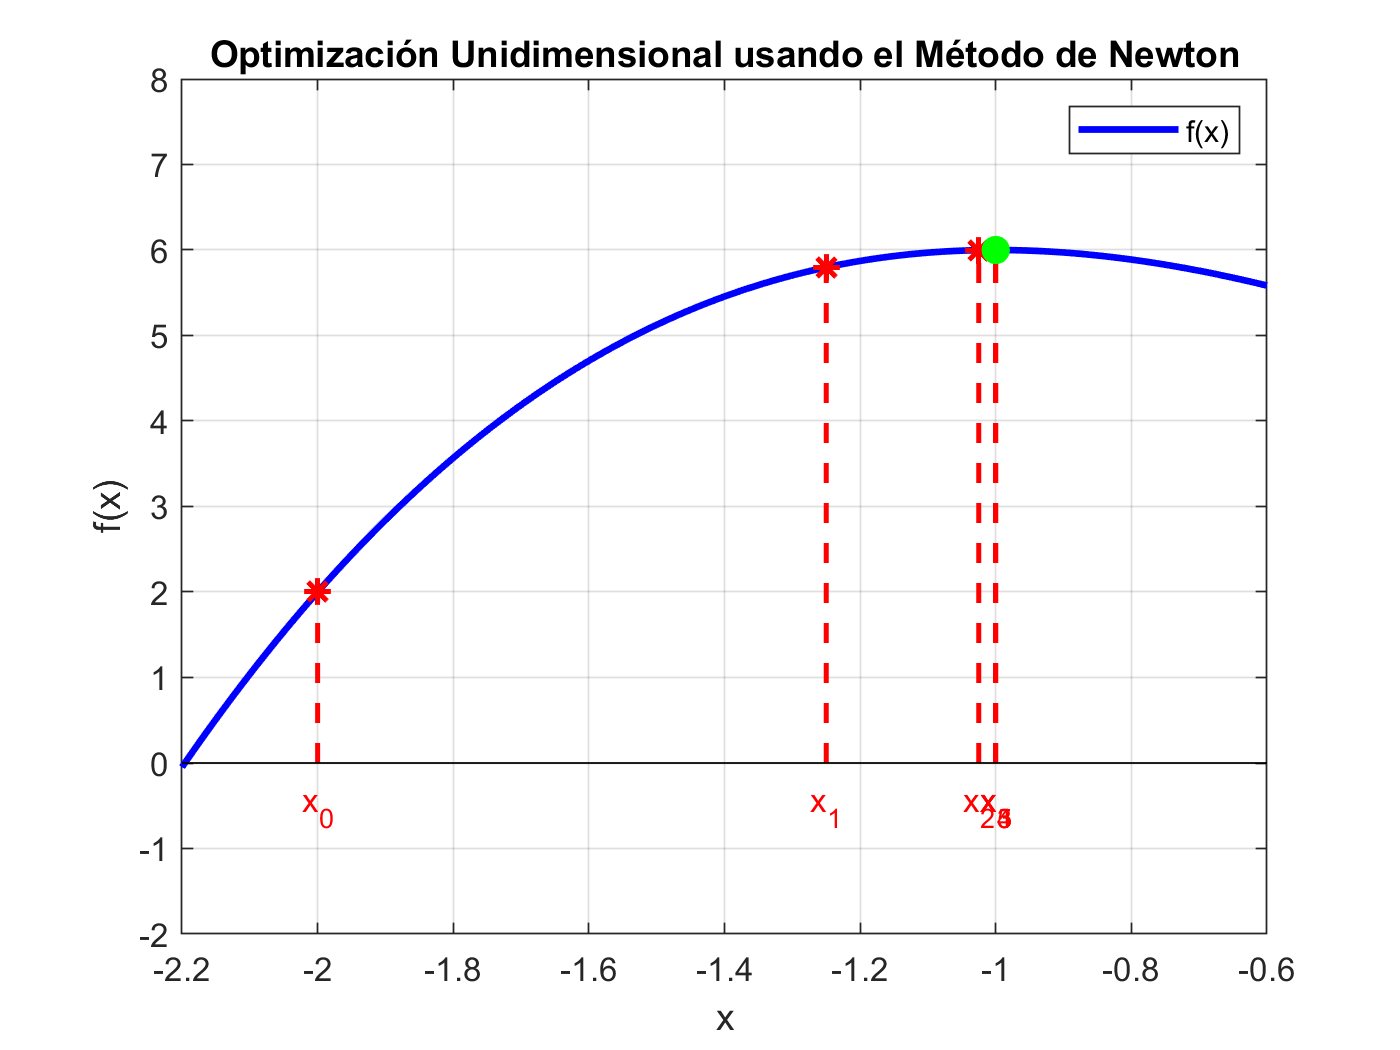


% Graficar la función y el progreso del método de Newton
x_vals = linspace(-2.2, -0.6, 1000);
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);  % Gráfico de la función
hold on;

% Graficar iteraciones como líneas verticales punteadas
for i = 1:length(x_hist)
    x_i = x_hist(i);
    plot([x_i, x_i], [0, f(x_i)], 'r--', 'LineWidth', 1.5); % Línea punteada
    text(x_i, -0.5, sprintf('x_%d', i-1), 'HorizontalAlignment', 'center', ...
        'FontSize', 10, 'Color', 'r'); % Etiqueta del punto
end

% Marcar iteraciones y solución óptima
plot(x_hist, f_hist, '*r', 'MarkerSize', 8, 'LineWidth', 1.5);  % Progreso del método
plot(x_opt, f_opt, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g'); % Solución óptima

% Ejes y configuración final
plot([min(x_vals), max(x_vals)], [0, 0], 'k', 'LineWidth', 0.5); % Eje x
ylim([-2, 8]);
xlabel('x');
ylabel('f(x)');
title('Optimización Unidimensional usando el Método de Newton');
legend('f(x)', 'Location', 'northeast');
grid on;
hold off;


% Mostrar los resultados finales
fprintf('Punto óptimo (x): %.6f\n', x_opt);

Punto óptimo (x): -1.000000


fprintf('Valor óptimo de f(x): %.6f\n', f_opt);

Valor óptimo de f(x): 6.000000
